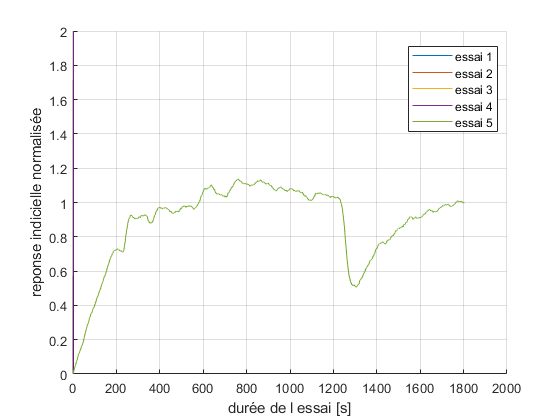

%avec boucle
%ysp=A(:,1);
a=diff(ysp);
ydif=a(a~=0);
xdif=find(a~=0);
clf; hold on; grid on

N = 4;   % A CHANGERRRR nombre d'essais FAUT CHANGER ICI SI CA DIT Index exceeds the number of array elements
for k = 1:N
    bi = xdif(k);      
    bf = xdif(k+1);    
    
    idx = bi:bf;
    yk = y(idx);

   
    y0 = yk(1);
    yk = yk - y0;

    % normalisation
    yinf = mean(yk(max(1,end-10):end));   % moyenne des 10 derniers points
    yk = yk / yinf;
    %yk=yk/max(ydif(k));
    t0 = idx - bi;
    plot(t0, yk);
end

% ---- DERNIER ESSAI : de xdif(end) jusqu'à la fin ----
bi = xdif(end);
bf = length(y);           % ou bf = length(t) si t existe et même taille

idx = bi:bf;
yk = y(idx);

y0 = yk(1);
yk = yk - y0;

yinf = mean(yk(max(1,end-10):end));
yk = yk / yinf;
%yk=yk/max(ydif(end));
t0 = idx - bi;
plot(t0, yk);


legend(compose("essai %d", 1:(N+1)), 'Location','best')
xlabel('durée de l essai [s]')

ylabel('reponse indicielle normalisée')


%Lancer simulink ,LAISSER ATTEINDRE LE REGIME EPRMANENT
%  faire ton scope , stoper la simulation, cliquer sur mise
%en forme indent
%remplacer le N par nombre echelon - 1 et lancer le code 

dm=d(bi:bf);
dm=dm-d(bi-10)

dm =      0
    10
    10
    10
    10
    10
    10
    10
    10
    10


yk=yk/max(dm)

yk =          0
    0.0001
   -0.0002
   -0.0000
    0.0006
    0.0016
    0.0019
    0.0018
    0.0017
    0.0016


dm=dm/max(dm)

dm =      0
     1
     1
     1
     1
     1
     1
     1
     1
     1


tm=bi:1:bf

tm =          974         975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010        1011        1012        1013        1014        1015        1016        1017        1018        1019        1020        1021        1022        1023


tm=tm-tm(1)

tm =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



ym=yk

ym =          0
    0.0001
   -0.0002
   -0.0000
    0.0006
    0.0016
    0.0019
    0.0018
    0.0017
    0.0016


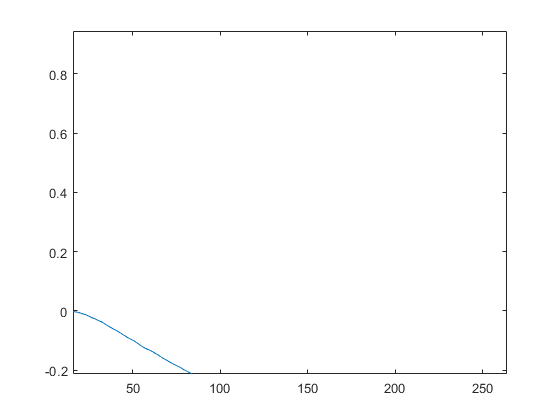

figure
plot(tm,ym,tm,dm)